# ATIC Final Project: CBF based Safe Formation Control for Wheeled Robots

**Author: Hang YIN (D-MAVT 20-954-236)**

*# This demo requires YALMIP toolbox*

## Global settings

clear
clear EvalCBF1 EvalCBF2 controller_ca1 controller_ca2
close all


N_agt = 10; % <<< number of agents
N_sim = 5000; % <<< simulation timesteps


please set GUI scaling first

% >>>>>>>>>>>>>>> Very important for plot objects size calibration <<<<<<<<<<<<<<<<<< %
% Set to 1 on MacOS as the OS scaling mechanism is very mature
GUI_Scale = 1.0;
% Set to the real GUI scaling on Windows/xNIX. The default scale is 100% for standard FHD screen, but can be 
% higher on High Resolution Screen.
% GUI_Scale = 2.0; % 200% Scaling


basic controller paramters defined here

global param
param.N_agt = N_agt; % number of agents
param.obstacles = [[3;0.5;0.6],[5;5;0.5],[1;4;2],[4;3;0.2]]; % obstacles location and size, [x,y,radius] for each
param.N_obs = size(param.obstacles,2); % number of obstacles
param.Ds = 0.3; % normal safety margin, can be violated but still stable
param.ahead = 0.8; % headway time
param.amax = 1; % unicycle max longitute acceleration
param.vmax = 1; % unicycle max longitute velocity
param.wmax = 2*pi; % unicycle max steering angular velocity
param.Ts = 0.02; % discretization time
param.K_fcn = @(x) 10*x^3; % <<< K_infty function
param.Dn = param.Ds + 1/(2*2*param.amax)*((2*2*param.amax/param.gamma)^(1/3)+2*param.vmax)^2; % See Urs, et al.
param.idx_lut = CalculateIdxLUT(N_agt,param.N_obs); % pair-wise index enumeration, will be improved in the future
param.G = GenerateRandomGraph(param.N_agt,0.7); % generate random sparse undirected graph, 
param.N_edge = size(param.G.Edges,1); % number of egdes of formation graph
param.Dg = kron([[1; zeros(param.N_agt-1,1)],full(incidence(param.G))],eye(2)); % incidence matrix D(D)

%>>>>>>>>>>>>>>>>>>>>>>>>>>> example1 <<<<<<<<<<<<<<<<<<<<<<<<<<<% not recommended, because the plot needs to be customized
% p0 = 2*[cos(linspace(0,2*pi-2*pi/N_agt,N_agt)); sin(linspace(0,2*pi-2*pi/N_agt,N_agt))]; % <<< initial posisiton of unicycles
% v0 = zeros(1,N_agt); % <<< initial speed for unicycles
% th0 = 2*pi*rand(1,N_agt); % <<< initial orientation for unicycles.
% x0 = [p0;v0;th0];

%>>>>>>>>>>>>>>>>>>>>>>>>>>> example2 <<<<<<<<<<<<<<<<<<<<<<<<<<<%
x0 = GenerateInitConfig(N_agt);
TargetFormationCerter = [8;8];
target_conf = GenerateTargetFormation(N_agt,TargetFormationCerter);

%>>>>>>>>>>>>>>>>>>>>>>>>>>> example3 <<<<<<<<<<<<<<<<<<<<<<<<<<<% not recommended, because the plot needs to be customized
% x0 = [[-0.1; -0.001; 0.01; pi],[0.1; 0.001; 0.01; 0]];
% target_conf = [[1.5; -0.01; 0],[-1.5; 0.01; pi]];

## Simulation loop

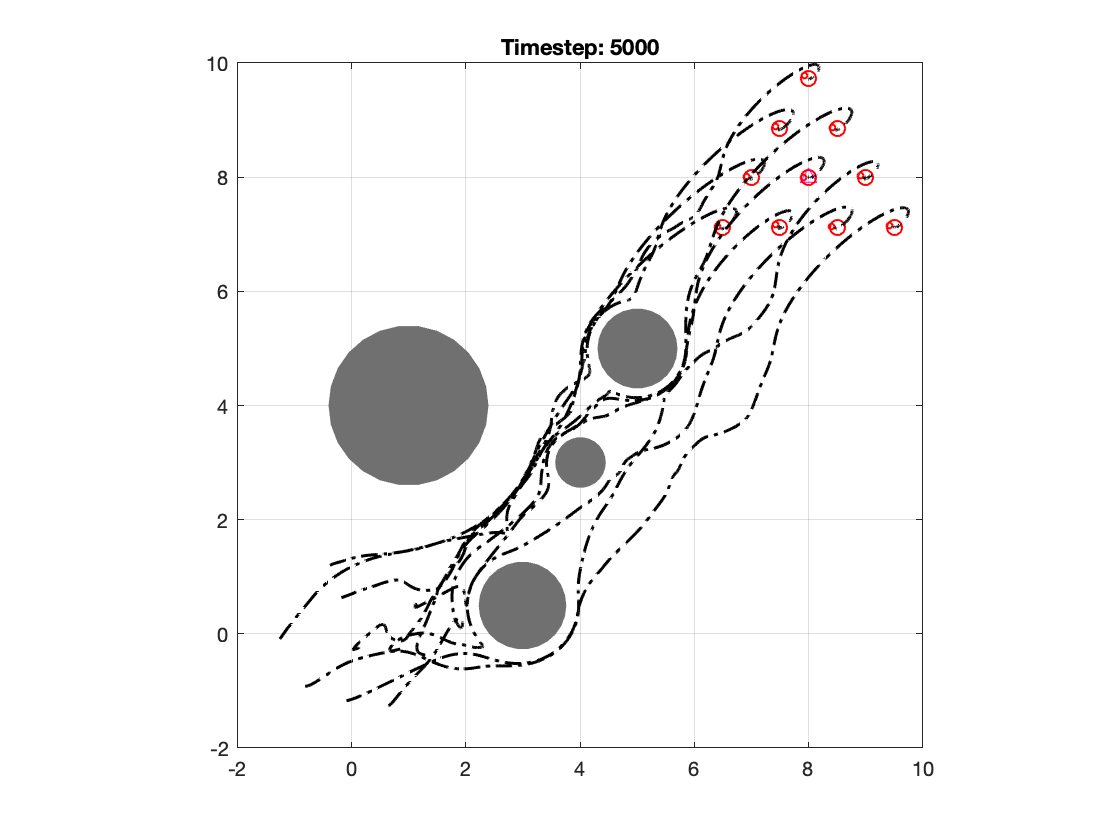

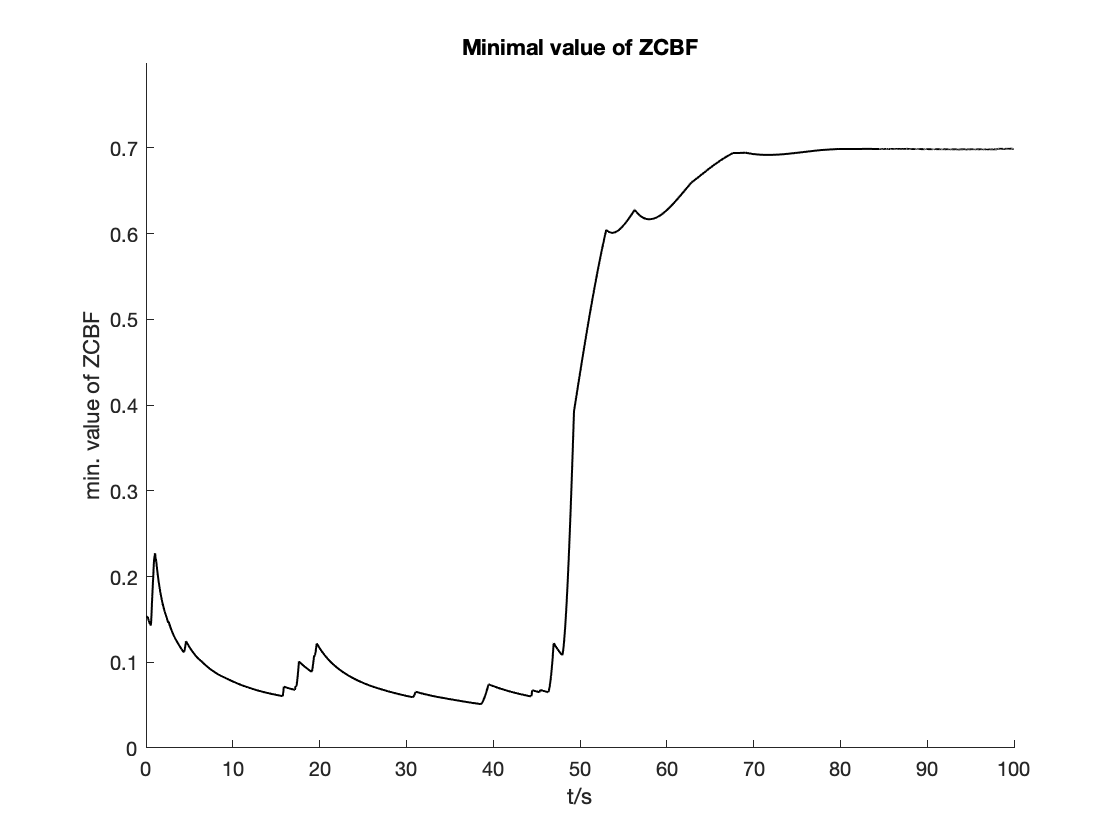

traj = zeros(4,N_agt,N_sim); % state trajectory record [x,y,v,theta]
traj(:,:,1) = x0; % first state set to initial state
CBFs_values = zeros(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs,N_sim-1);
min_CBF_value = zeros(1,N_sim-1);

u_nc = zeros(2,N_agt);
u = zeros(2,N_agt);

for t = 2:N_sim

    % top level nominal controller (NC)
    u_nc = TopController(traj(:,:,t-1), target_conf);
    
    % CBF-QP for double integrators (QP1). (FL) is included in this layer
    [u,~] = controller_ca1(eye(2), traj(:,:,t-1), u_nc); 
    
    % CBF-QP for unicycles (QP2)
    [u,CBFs_values(:,t-1)] = controller_ca2(diag([1 1]), traj(:,:,t-1), u);
    min_CBF_value(t-1) = min(CBFs_values(:,t-1));
    
    % solve ode in each sample time, solve dynamic for each unicycle
    for m = 1:N_agt
        [~,xi] = ode45(@(t,x) UnicycleDynamic(t,x,u(1,m),u(2,m)), [0,param.Ts], traj(:,m,t-1));
        traj(:,m,t) = xi(end,:)';
    end
 
    % animation
    figure(1)
    hb = scatter(squeeze(traj(1,:,t)),squeeze(traj(2,:,t)),GUI_Scale^-1*200*param.Ds,'MarkerFaceColor','none','MarkerEdgeColor','red','LineWidth',1.0);
    if t == 2
        hold on, box on, grid on, axis square
        xlim([-2,10]), ylim([-2,10]);
        % draw obstacles
        scatter(param.obstacles(1,:),param.obstacles(2,:),GUI_Scale^-1*3200*param.obstacles(3,:),'MarkerFaceColor','#707070','MarkerEdgeColor','none');
        scatter(TargetFormationCerter(1),TargetFormationCerter(2),50,'magenta','^');
    end
    % draw robot heading mark
    hd = scatter(squeeze(traj(1,:,t))+0.3*param.Ds*squeeze(cos(traj(4,:,t))), squeeze(traj(2,:,t))+0.3*param.Ds*squeeze(sin(traj(4,:,t))), 10, 'MarkerEdgeColor','red','LineWidth',1.0);
    title(['Timestep: ',num2str(t)])
    % draw paths
    for m = 1:N_agt
        hl(m) = plot(squeeze(traj(1,m,1:t)),squeeze(traj(2,m,1:t)),'Color','black','LineStyle','-.','LineWidth',1.0);
    end
    drawnow

    % plot CBF values
    figure(2)
    if t >= 3
        line(param.Ts*(t-2:t-1),min_CBF_value(t-2:t-1),'Color','black','LineWidth',1.0);
        CBF_max = max(min_CBF_value(1:t-1));
        CBF_min = min(min_CBF_value(1:t-1));
        if t == 3
            hold on
            title('Minimal value of ZCBF')
            xlim([0,param.Ts*N_sim]);
            xlabel('t/s')
            ylabel('min. value of ZCBF')
        end
        ylim([min([0,CBF_min]),CBF_max+0.1]);
        drawnow
    end
    % refresh
    if t ~= N_sim
        delete(hb)
        delete(hd)
        delete(hl(:))
    end

end

## Cascaded Controller

### Top level controller

simple absolute position PD controller, others can also be used including networked/relative control

state vector: $[x,y,v,\theta] \in \mathrm{R}^4$

target conf: $[x^*,y^*]$, we cannot control the final orientation at this time

It can be shown that as long as the damp factor $D>\sqrt{\frac{4}{\min \left(\mathrm{abs}\left(\mu_i \right)\right)}}$, the system is damped without oscillation (imaginary eigenvalues).

function u_cart = TopController(uni_state, target_conf)
global param
k = 1;
damp = 4;

cart_state = Uni2Cart(uni_state);

% vectorize state
x = reshape(cart_state(1:2,:),[],1);
dx = reshape(cart_state(3:4,:),[],1);
x_ref = reshape(target_conf(1:2,:),[],1);

% RSS-PD
z_ref = param.Dg'* x_ref;

z = param.Dg'*x;
dz = param.Dg'*dx;

e = z_ref-z;
de = -dz;

u_cart = param.Dg*(k*e+damp*k*de);
u_cart = reshape(u_cart,2,[]);

end

### 1st level controller using double integrator modelling

function [u,CBFs_value] = controller_ca1(R, state, u_ref)
% controller variables
persistent yalmip_optimizer
global param

% initialize parameters, if not done already
if isempty(yalmip_optimizer)
    yalmip_optimizer = init_ca1(R);
end

% convert to cartesian state
cart_state = Uni2Cart(state);


% Calculate CBF affine constraints matrix
A_cbf = zeros(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs, 2*param.N_agt);
b_cbf = zeros(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs, 1);
idx_lut = param.idx_lut;
N_agt = param.N_agt;
param_local = param;
CBFs_value = zeros(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs,1);

for k = 1:N_agt*(N_agt-1)+param.N_agt*param.N_obs
    i = idx_lut{k}(1);
    j = idx_lut{k}(2);

    if k <= N_agt*(N_agt-1)
        [Aij,bij,CBFs_value(k)] = EvalCBF1(cart_state(:,i), cart_state(:,j), param_local, 'normal');

        A_cbf_slice = zeros(1,2*N_agt);

        A_cbf_slice(2*(i-1)+1) = Aij(1);
        A_cbf_slice(2*(i-1)+2) = Aij(2);
        A_cbf_slice(2*(j-1)+1) = Aij(3);
        A_cbf_slice(2*(j-1)+2) = Aij(4);

        A_cbf(k,:) = A_cbf_slice;
        b_cbf(k) = bij;
    else
        [Aio,bio,CBFs_value(k)] = EvalCBF1(cart_state(:,i), param_local.obstacles(:,j-N_agt), param_local, 'obstacle');
        A_cbf_slice = zeros(1,2*N_agt);

        A_cbf_slice(2*(i-1)+1) = Aio(1);
        A_cbf_slice(2*(i-1)+2) = Aio(2);

        A_cbf(k,:) = A_cbf_slice;
        b_cbf(k) = bio;
    end


end


% call optimizer
u_cart = yalmip_optimizer({u_ref, A_cbf, b_cbf});

% transform into unicycle control input [a,w], each column for one agent
u = zeros(2,param.N_agt);
for m = 1:param.N_agt
    if state(3,m) < 0.001
    % singularity handling
        phi_ref_cart = atan2(u_cart(2,m),u_cart(1,m));
        d_phi = phi_ref_cart-state(4,m);
        if abs(d_phi) < 1e-6
            phi_err = 0;
        else
            phi_err = sign(sin(d_phi))*acos(cos(d_phi));
        end
        if abs(phi_err) > 0.1
            u(:,m) = [0;10*phi_err];
            %disp('1')
        else
            u(:,m) = [cos(state(4,m)), sin(state(4,m));
                    -sin(state(4,m))/(state(3,m)+1e-6), cos(state(4,m))/(state(3,m)+1e-6)] * u_cart(:,m);
            %disp('2')
        end
    else
        u(:,m) = [cos(state(4,m)), sin(state(4,m));
                 -sin(state(4,m))/(state(3,m)+1e-6), cos(state(4,m))/(state(3,m)+1e-6)] * u_cart(:,m);
        %disp('3')
    end
end

end

function yalmip_optimizer = init_ca1(R)
% Fetch controller parameters
global param

% LCQP modeling
u = sdpvar(2,param.N_agt,'full');
u_ref = sdpvar(2,param.N_agt,'full');
A_cbf = sdpvar(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs, 2*param.N_agt,'full');
b_cbf = sdpvar(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs, 1, 'full');

% constraint
constraint = A_cbf*reshape(u,[],1) <= b_cbf; % <<< CBF constraints, cartesian

% objective
objective = trace((u-u_ref)'*R*(u-u_ref));

opts = sdpsettings('verbose', 0, 'solver','quadprog');
yalmip_optimizer = optimizer(constraint, objective, opts, {u_ref, A_cbf, b_cbf}, u);

end

### 2nd level CBF controller handling unicycle hard constraints

function [u,CBFs_value] = controller_ca2(R, state, u_ref)
% controller variables
global param
persistent yalmip_optimizer

% initialize parameters, if not done already
if isempty(yalmip_optimizer)
    yalmip_optimizer = init_ca2(R);
end

% Calculate CBF affine constraints matrix
A_cbf = zeros(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs, 2*param.N_agt);
b_cbf = zeros(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs, 1);
idx_lut = param.idx_lut;
N_agt = param.N_agt;
param_local = param;
CBFs_value = zeros(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs,1);

for k = 1:N_agt*(N_agt-1)+param.N_agt*param.N_obs
    i = idx_lut{k}(1);
    j = idx_lut{k}(2);

    if k <= N_agt*(N_agt-1)
        [Aij,bij,CBFs_value(k)] = EvalCBF2(state(:,i), state(:,j), param_local, 'normal');

        A_cbf_slice = zeros(1,2*N_agt);

        A_cbf_slice(2*(i-1)+1) = Aij(1);
        A_cbf_slice(2*(i-1)+2) = Aij(2);
        A_cbf_slice(2*(j-1)+1) = Aij(3);
        A_cbf_slice(2*(j-1)+2) = Aij(4);

        A_cbf(k,:) = A_cbf_slice;
        b_cbf(k) = bij;
    else
        [Aio,bio,CBFs_value(k)] = EvalCBF2(state(:,i), param_local.obstacles(:,j-N_agt), param_local, 'obstacle');
        A_cbf_slice = zeros(1,2*N_agt);

        A_cbf_slice(2*(i-1)+1) = Aio(1);
        A_cbf_slice(2*(i-1)+2) = Aio(2);

        A_cbf(k,:) = A_cbf_slice;
        b_cbf(k) = bio;
    end
end


% call optimizer
u = yalmip_optimizer({u_ref, A_cbf, b_cbf, state(3,:)});

end

function yalmip_optimizer = init_ca2(R)
% Fetch controller parameters
global param

% LCQP modeling
u = sdpvar(2,param.N_agt,'full');
u_ref = sdpvar(2,param.N_agt,'full');
A_cbf = sdpvar(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs, 2*param.N_agt,'full');
b_cbf = sdpvar(param.N_agt*(param.N_agt-1)+param.N_agt*param.N_obs, 1, 'full');
velocity = sdpvar(1,param.N_agt,'full');

% constraint
constraint = A_cbf*reshape(u,[],1) <= b_cbf; % <<< CBF constraints, unicycle
constraint = [constraint, -param.amax <= u(1,:) <= param.amax]; % <<< unicycle control input constraint
constraint = [constraint, -param.wmax <= u(2,:) <= param.wmax]; % <<< unicycle control input constraint
constraint = [constraint, -param.vmax <= velocity + u(1,:)*param.Ts <= param.vmax]; % <<< unicycle velocity constraint

% objective
objective = trace((u-u_ref)'*R*(u-u_ref));

opts = sdpsettings('verbose', 0, 'solver','quadprog');
yalmip_optimizer = optimizer(constraint, objective, opts, {u_ref, A_cbf, b_cbf, velocity}, u);

end

### Evaluate CBF certificate for double integrator (1st layer)

mode: 'normal', 'obstacle'

if use obstacle mode, state_j:=[x_o,y_o,D_o]

function [A,b,h] = EvalCBF1(state_i, state_j, param, mode)

persistent hij Lij hio Lio

 if isempty(hij)
    syms xi yi vxi vyi xj yj vxj vyj axi ayi axj ayj D Do real

    vi_bar = [xj-xi;yj-yi]'*[vxi;vyi]/norm([xi-xj;yi-yj]);
    vj_bar = [xj-xi;yj-yi]'*[vxj;vyj]/norm([xi-xj;yi-yj]);   
    hij = (D-param.Ds)-param.ahead*(vi_bar-vj_bar);
    hio = (D-param.Ds-Do)-param.ahead*(vi_bar);

    Lij = jacobian(hij,[D xi yi vxi vyi xj yj vxj vyj]) * [vj_bar-vi_bar; vxi; vyi; axi; ayi; vxj; vyj; axj; ayj];
    Lij = simplify(Lij); % <<< lie derivative of hij
    hij = simplify(hij);

    Lio = jacobian(hio,[D xi yi vxi vyi xj yj]) * [-vi_bar; vxi; vyi; axi; ayi; 0; 0];
    Lio = simplify(Lio);
    hio = simplify(hio);
    
    % generate function call
    hij = matlabFunction(hij,'Vars',{D,[xi;yi;vxi;vyi],[xj;yj;vxj;vyj]});
    Lij = matlabFunction(Lij,'Vars',{axi,ayi,axj,ayj,[xi;yi;vxi;vyi],[xj;yj;vxj;vyj]});
    hio = matlabFunction(hio,'Vars',{D,[xi;yi;vxi;vyi],[xj;yj;Do]});
    Lio = matlabFunction(Lio,'Vars',{axi,ayi,[xi;yi;vxi;vyi],[xj;yj;Do]}); % <<< Do is stumb variable here
end

% guarantee column state vector
state_i = reshape(state_i,[],1);
state_j = reshape(state_j,[],1);

if strcmp(mode,'normal')
    % evaluate hij Lij
    D_eval = norm(state_i(1:2) - state_j(1:2));
    hij_eval = hij(D_eval,state_i,state_j);
    c0 = Lij(0,0,0,0,state_i,state_j);
    c1 = Lij(1,0,0,0,state_i,state_j) - c0;
    c2 = Lij(0,1,0,0,state_i,state_j) - c0;
    c3 = Lij(0,0,1,0,state_i,state_j) - c0;
    c4 = Lij(0,0,0,1,state_i,state_j) - c0;

    A = [-c1,-c2,-c3,-c4];
    b = param.K_fcn(hij_eval) + c0;
    h = hij_eval;

elseif strcmp(mode, 'obstacle')
    D_eval = norm(state_i(1:2) - state_j(1:2));
    hio_eval = hio(D_eval,state_i,state_j);
    c0 = Lio(0,0,state_i,state_j);
    c1 = Lio(1,0,state_i,state_j) - c0;
    c2 = Lio(0,1,state_i,state_j) - c0;

    A = [-c1,-c2];
    b = param.K_fcn(hio_eval) + c0;
    h = hio_eval;
else
    error("only use mode: 'normal', 'obstacle'");
end


end

### Evaluate CBF certificate for unicycle (2nd layer)

function [A,b,h] = EvalCBF2(state_i, state_j, param, mode)

persistent hij Lij hio Lio

if isempty(hij)
    syms xi yi vi thi xj yj vj thj ai aj wi wj D Do real

    vi_bar = [xj-xi;yj-yi]'*[vi*cos(thi);vi*sin(thi)]/norm([xi-xj;yi-yj]);
    vj_bar = [xj-xi;yj-yi]'*[vj*cos(thj);vj*sin(thj)]/norm([xi-xj;yi-yj]);   
    hij = (D-param.Ds)-param.ahead*(vi_bar-vj_bar);
    hio = (D-param.Ds-Do)-param.ahead*(vi_bar);

    Lij = jacobian(hij,[D, xi,xj,yi,yj,vi,vj,thi,thj]) * [vj_bar-vi_bar; vi*cos(thi);vj*cos(thj);vi*sin(thi);vj*sin(thj);ai;aj;wi;wj];
    Lij = simplify(Lij); % <<< lie derivative of hij
    hij = simplify(hij);

    Lio = jacobian(hio,[D, xi,xj,yi,yj,vi,thi]) * [-vi_bar; vi*cos(thi); 0; vi*sin(thi); 0; ai; wi];
    Lio = simplify(Lio);
    hio = simplify(hio);

    % Generate function
    hij = matlabFunction(hij,'Vars',{D,[xi;yi;vi;thi],[xj;yj;vj;thj]});
    Lij = matlabFunction(Lij,'Vars',{ai,wi,aj,wj,[xi;yi;vi;thi],[xj;yj;vj;thj]});
    hio = matlabFunction(hio,'Vars',{D,[xi;yi;vi;thi],[xj;yj;Do]});
    Lio = matlabFunction(Lio,'Vars',{ai,wi,[xi;yi;vi;thi],[xj;yj;Do]});
end

% guarantee column state vector
state_i = reshape(state_i,[],1);
state_j = reshape(state_j,[],1);


if strcmp(mode,'normal')
    % evaluate hij Lij
    D_eval = norm(state_i(1:2) - state_j(1:2));
    hij_eval = hij(D_eval,state_i,state_j);
    c0 = Lij(0,0,0,0,state_i,state_j);
    c1 = Lij(1,0,0,0,state_i,state_j) - c0;
    c2 = Lij(0,1,0,0,state_i,state_j) - c0;
    c3 = Lij(0,0,1,0,state_i,state_j) - c0;
    c4 = Lij(0,0,0,1,state_i,state_j) - c0;

    A = [-c1,-c2,-c3,-c4];
    b = param.K_fcn(hij_eval) + c0;
    h = hij_eval;

elseif strcmp(mode, 'obstacle')
    D_eval = norm(state_i(1:2) - state_j(1:2));
    hio_eval = hio(D_eval,state_i,state_j);
    c0 = Lio(0,0,state_i,state_j);
    c1 = Lio(1,0,state_i,state_j) - c0;
    c2 = Lio(0,1,state_i,state_j) - c0;

    A = [-c1,-c2];
    b = param.K_fcn(hio_eval) + c0;
    h = hio_eval;
else
    error("only use 'normal' or 'obstacle'");
end
end

### Unicycle dynamic

function dxdt = UnicycleDynamic(~,state,F,w)

dxdt = zeros(4,1);

dxdt(1) = state(3)*cos(state(4));
dxdt(2) = state(3)*sin(state(4));
dxdt(3) = F;
dxdt(4) = w;

end

## Helper function

### convert unicycle state to cartesian state

cartesian state: $x_{cart} = [x,y,\dot{x},\dot{y}]$

function cart_state = Uni2Cart(uni_state)
cart_state = [uni_state(1:2,:); uni_state(3,:).*cos(uni_state(4,:)); uni_state(3,:).*sin(uni_state(4,:))];
end

### generate initial configuration

function x_init = GenerateInitConfig(N_agt)
global param
R = 2; % robots randomly located in disk centered at origin
x = zeros(1,N_agt);
y = zeros(1,N_agt);
phi = 2*pi*rand(1,N_agt);
v = zeros(1,N_agt);

r = R*rand();
theta = 2*pi*rand();
x(1) = sqrt(r)*cos(theta);
y(1) = sqrt(r)*sin(theta);
cnt = 1;
for k = 2:N_agt
    r = R*rand();
    theta = 2*pi*rand();
    x_temp = sqrt(r)*cos(theta);
    y_temp = sqrt(r)*sin(theta);
    while ~CheckSafety(x_temp, y_temp, cnt)
        r = R*rand();
        theta = 2*pi*rand();
        x_temp = sqrt(r)*cos(theta);
        y_temp = sqrt(r)*sin(theta);
    end
    x(k) = x_temp;
    y(k) = y_temp;
    cnt = cnt+1;
end

x_init = [x;y;v;phi];

    function isSafe = CheckSafety(x_temp, y_temp, cnt)
        dist = sqrt((x(1:cnt)-x_temp).^2 + (y(1:cnt)-y_temp).^2);
        if all(dist > 1.5*param.Ds)
            isSafe = true;
        else
            isSafe = false;
        end
    end

end

### generate billiard demo formation

function x_tg = GenerateTargetFormation(N_agt, FormationCenter)
% demo: billiard formation

row = -0.5 + sqrt(1+8*N_agt)/2;

if abs(row-round(row)) > 1e-6
    error("inappropriate number of agents to form billiard formation!")
end

dx = 1*sin(pi/6);
dy = 1*cos(pi/6);

x_tg = [];

for k = 1:row
    if k == 1
        head = [0; 0];
    else
        head = head + [dx; -dy];
    end
    cnt = row-(k-1);
    x_tg = [x_tg, head + [-dx*(0:cnt-1); -dy*(0:cnt-1)]];
end
    % center the final formation
    centroid = (x_tg(:,1) + x_tg(:,row) + x_tg(:,N_agt))/3;
    %center = center/2 + x_tg(:,1)/2;
    x_tg = x_tg - centroid +  FormationCenter;
end

### Calculate index lookup table for parallel computing (if needed)

function idx_lut = CalculateIdxLUT(N_agt, N_obs)
idx_lut = cell(1,N_agt*(N_agt-1) + N_agt*N_obs);
cnt = 0;
for i = 1:N_agt
    for j = 1:N_agt
    if i == j
        continue;
    end
    cnt = cnt + 1;
    idx_lut{cnt} = [i,j];
    end
end


for i = 1:N_agt
    for j = 1:N_obs
    cnt = cnt+1;
        idx_lut{cnt} = [i,j+N_agt];
    end
end

end

### generate random sparse graph

% p controls sparsity, must be larger than 0.5
function G = GenerateRandomGraph(n,p)
A = round(p*rand(n));
A = triu(A) + triu(A,1)';
A = A - diag(diag(A));
% check connectivity
while max(mink(eig(laplacian(graph(A))),2)) < 1e-6
    A = round(p*rand(n));
    A = triu(A) + triu(A,1)';
    A = A - diag(diag(A));
end
G = graph(A);
end